clc;clear;
%im=imread('cat.jpg');
%im=imread('d.jpg');
im=imread('lena.tif');

## 像素值转为yuv

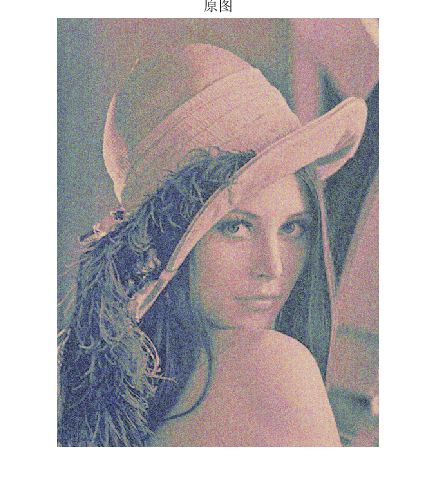

im_yuv = func_rgb2yuv(im);

yuv1_1 = im_yuv(:,:,2);
yuv1_2 = im_yuv(:,:,3);
figure; imshow( func_yuv2rgb( im_yuv));
title('原图'); % 显示原图

## 对色度图像二次采样

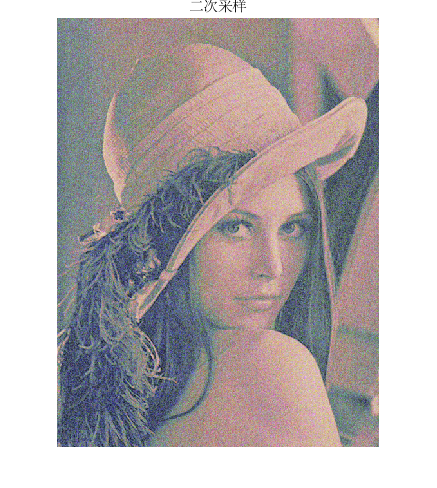

im_yuv = func_subsampling_420( im_yuv);

yuv2_1 = im_yuv(:,:,2);
yuv2_2 = im_yuv(:,:,3);
figure; imshow( func_yuv2rgb( im_yuv));
title('二次采样'); % 显示二次采样图

## 对图像分块8*8并DCT变换

im_dct = func_dct(im_yuv);

## 量化 丢弃不显著信息分块

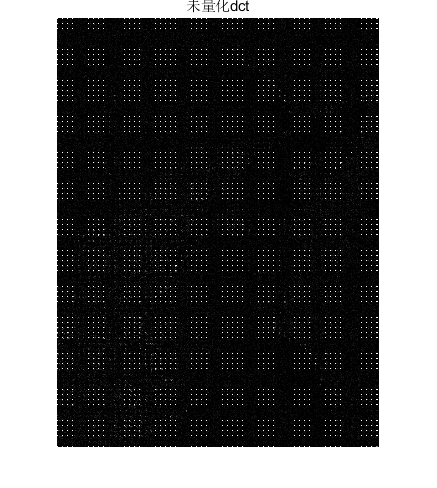

im_dct2 = func_quality( im_dct);

dct1 = im_dct(:,:,1);
dct2 = im_dct2(:,:,1);
figure; imshow( uint8( im_dct(:,:,1))); title('未量化dct');

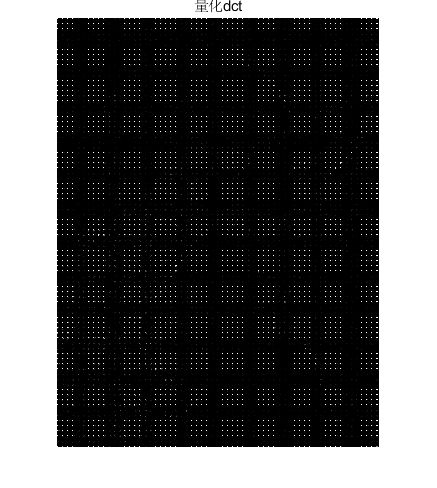

figure; imshow( uint8( im_dct2(:,:,1))); title('量化dct');

imwrite(uint8( im_dct(:,:,1)),'未量化dct.jpg','jpg');
imwrite( uint8( im_dct2(:,:,1)),'量化dct.jpg','jpg');

## IDCT变换 显示

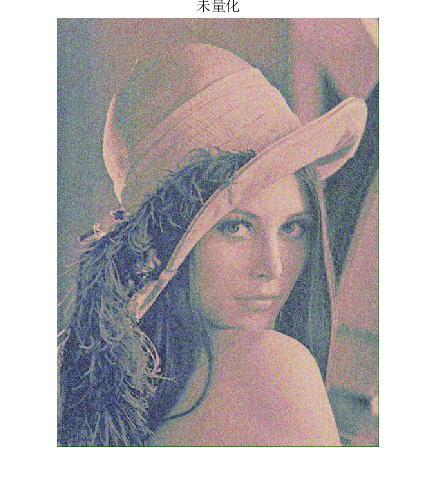

im_idct = func_idct( im_dct);
im_idct2 = func_idct( im_dct2);

figure; imshow( func_yuv2rgb( im_idct));
title('未量化'); % 显示IDCT结果

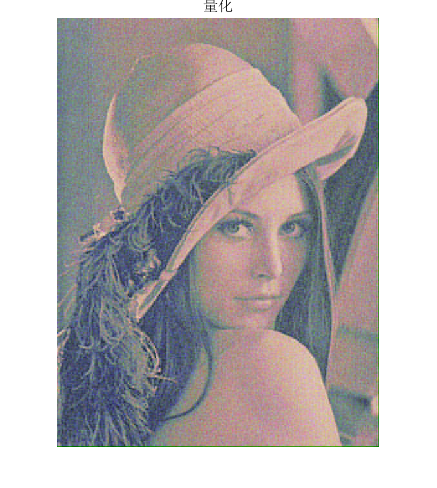

imwrite(func_yuv2rgb( im_idct),'未量化.jpg','jpg');

figure; imshow( func_yuv2rgb( im_idct2));
title('量化'); % 显示量化IDCT结果

imwrite(func_yuv2rgb( im_idct2),'量化.jpg','jpg');